## Image presentation and analysis

## Part D: Terrestrial imagery

So far, we have focussed on the presentation and brief analysis of satellite imagery (landsat, sentinel, planet). Whilst the improvements in spatial and temporal resolution of satellite-borne imagery has be profound over the last two decades, satellite imagery is currently incapable of detecting small scale (<< 1 m) changes, or at least not without significant financial outlay. In these instances, the deployment of trail cameras, uncrewed aerial systems (drones), and repeat imagery using standard digital cameras can be valuable tools for detecting change in the landscape over time.

In this example, we are going to briefly introduce a method for detecting change between two images acquired from the same location, with the same view. The location where the camera is located is the Rio Este on the hills of Volcán Calbuco, which violently erupted in 2015. Since then, the river has been actively reworking the material exposed by the eruption. The two images were taken one-day apart. Let's start by bringing in the imagery and displaying the imagery that we will be working with:

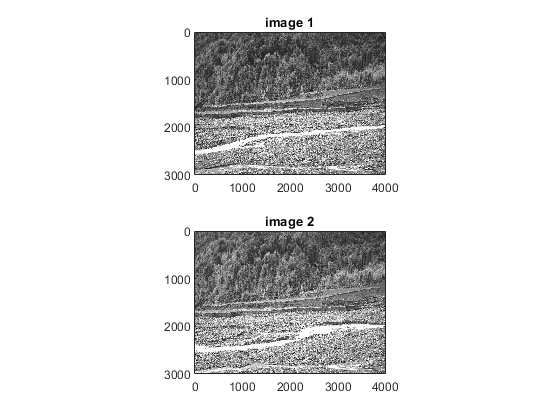

clear all; close all; clc
dirIn = 'C:\_git_local\GEO8026_21_22\Block 05\data\calbuco\';

% Calculate the pixelwise difference between the two images
im1 = rgb2gray(imread([dirIn 'IMAG0294.jpg']));
im2 = rgb2gray(imread([dirIn 'IMAG0301.jpg']));

f0 = figure(); hold on;
ax0_1 = subplot(2,1,1); % subplots allow us to display multiple plots in one figure
imagesc(im1); hold on
axis equal
set(ax0_1,'xlim',[0 4000]);
set(ax0_1,'ylim',[0 3000]);
colormap(ax0_1, 'gray');
title('image 1');

ax0_2 = subplot(2,1,2); % subplots allow us to display multiple plots in one figure
imagesc(im2); hold on
axis equal
set(ax0_2,'xlim',[0 4000]);
set(ax0_2,'ylim',[0 3000]);
colormap(ax0_2, 'gray');
title('image 2');

% link the axes so they respond the same
linkaxes([ax0_1 ax0_2],'xy')

Now we will start to undertake some analysis of the imagery. Let's start by seeing how the properties of the images differ on a pixel-by-pixel basis. We can do this by converting the RGB image into a grayscale image (intensity only), and through simple subtraction we can see how the values of the pixels vary. We can set a threshold for change detection (in this case a value of 50). Then, we search for adjacent pixels that meet this threshold and begin to identify whole areas of the image that have changed. The upper right image shows areas where the pixel intensity value has changed by > 50. 

f1 = figure(); hold on;
ax1 = subplot(2,2,1); % subplots allow us to display multiple plots in one figure
imagesc(im2); hold on
colormap(ax1, 'gray');
title(['image 2']);

% Analyse the pixelwise differences
diff1 = im2-im1;
ax2 = subplot(2,2,2); % subplots allow us to display multiple plots in one figure

th      = 50;
a       = diff1(:,:,1) > th; % find pixel values greater than 50
a       = bwareaopen(a,100,4); % find 100+ connected pixels
B       = bwboundaries(a,'noholes');

warning('off')
mask1 = [];
sz = size(im2);

for c = 1:length(B)
    filled  = polyshape (B{c,1}(:,1),B{c,1}(:,2)); % polyshape
    b = regions(filled); % extract the regions
    for d = 1:length(b)
        if ~isempty(b(d,1).Vertices(:,1))
            temp1   = [b(d,1).Vertices(:,1),b(d,1).Vertices(:,2)];
            isx     = find(~isnan(temp1(:,1)));
            dataIn  = [temp1(isx,1),temp1(isx,2)];
            
            BW1 = poly2mask(dataIn(:,2),dataIn(:,1),...
                sz(1),sz(2));
            mask1 = [mask1; find(BW1>0)];
            
        end
    end
end

% Plot the outputs
im2_1 = double(im2);
im2_1(mask1) = NaN;
imagesc(im2_1)
cMap1 = parula(256);
cMap1(1,:) = 1;
colormap(ax2, cMap1);
colorbar
title(['intensity change > ' num2str(th) ' as white']);

However, in instances where the pixel intensity values are low (e.g. < 10) to begin with (i.e. dark areas), small changes in the absolute intensity values can result in a relatively large change in intensity when expressed as a percentage change. In these instances, it may be appropriate to set a threshold change based on the percentage change in pixel intensity. In this example, we will set this the threshold detection value as 1.5 i.e. a 50% change in intensity between the two images.

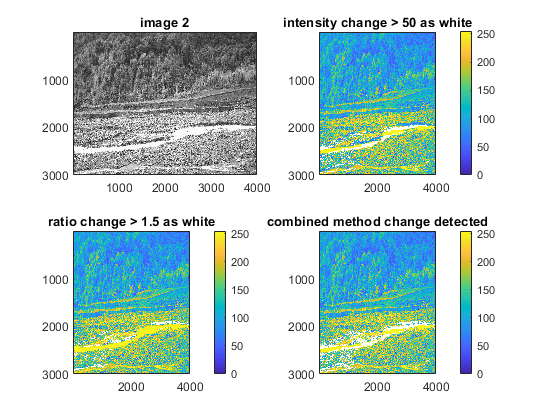

% Calculate the pixelwise ratio between the two images
ratio1 = abs(im1./im2);

th      = 1.5;
a       = ratio1(:,:,1) > th; % find pixel values that have changed by > 50%
a       = bwareaopen(a,100,4); % find 100+ connected pixels
B2      = bwboundaries(a,'noholes');

warning('off')
mask2 = [];

for c = 1:length(B2)
    filled  = polyshape (B2{c,1}(:,1),B2{c,1}(:,2)); % polyshape
    b = regions(filled); % extract the regions
    for d = 1:length(b)
        if ~isempty(b(d,1).Vertices(:,1))
            temp1   = [b(d,1).Vertices(:,1),b(d,1).Vertices(:,2)];
            isx     = find(~isnan(temp1(:,1)));
            dataIn  = [temp1(isx,1),temp1(isx,2)];
            
            BW2 = poly2mask(dataIn(:,2),dataIn(:,1),...
                sz(1),sz(2));
            mask2 = [mask2; find(BW2>0)];
        end
    end
end

% Plot the outputs of the ratio differences
ax3 = subplot(2,2,3); % subplots allow us to display multiple plots in one figure
im2_2 = double(im2);
im2_2(mask2) = NaN;
imagesc(im2_2)
cMap3 = parula(256);
cMap3(1,:) = 1;
colormap(ax3, cMap3);
colorbar
title(['ratio change > ' num2str(th) ' as white']);

% plot the area with combined change detection
ax4 = subplot(2,2,4); 
mask = [mask1; mask2];
im2_2 = double(im2);
im2_2(mask) = NaN;
imagesc(im2_2)
cMap3 = parula(256);
cMap3(1,:) = 1;
colormap(ax4, cMap3);
colorbar
title(['combined method change detected']);